% Position and angle matrices
position_mid = [0.9,1.8,2.7,3.6];
position_side = 0.9*(0:8)+5.6;
position_out = 0.9*(0:4)+15;
positions = [-flip(position_out), -flip(position_side), -flip(position_mid), 0, position_mid, position_side, position_out];
theta1 = atan(positions/19.5)

theta1 =    -0.7618   -0.7370   -0.7112   -0.6841   -0.6557   -0.5809   -0.5479   -0.5136   -0.4779   -0.4408   -0.4024   -0.3627   -0.3218   -0.2797   -0.1826   -0.1376   -0.0920   -0.0461         0    0.0461    0.0920    0.1376    0.1826    0.2797    0.3218    0.3627    0.4024    0.4408    0.4779    0.5136    0.5479    0.5809    0.6557    0.6841    0.7112    0.7370    0.7618


theta1 = theta1';

thetaAS = atan((positions-0.9)/19.5);
thetaAS = thetaAS';

thetaVEML = atan((positions+0.9)/19.5);
thetaVEML = thetaVEML';

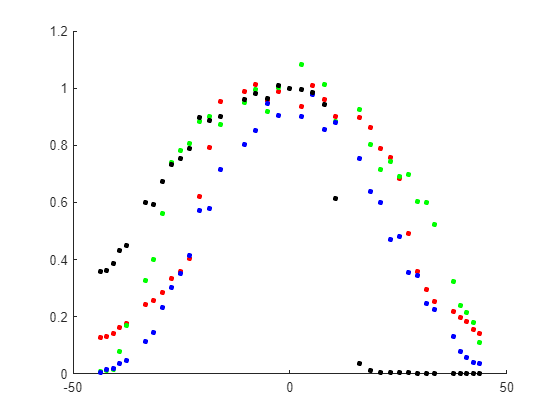


% Get data and scale the different integration times
WHITE_100_Angles_Further_Scaled = scale(WHITE_100_Angles_Further);
W_100_Further_M = transpose(reshape(cell2mat(WHITE_100_Angles_Further_Scaled(:,3)),9,15));
WHITE_100_Angles_Further_L_Scaled = scale2(WHITE_100_Angles_Further_L);
W_100_Further_L = transpose(reshape(cell2mat(WHITE_100_Angles_Further_L_Scaled(:,3)),[],15));
WHITE_100_Angles_Further_R_Scaled = scale2(WHITE_100_Angles_Further_R);
W_100_Further_R = transpose(reshape(cell2mat(WHITE_100_Angles_Further_R_Scaled(:,3)),[],15));

W_100_Further = [W_100_Further_R, W_100_Further_M, W_100_Further_L];

W_100_Further_normaliseW_AS = W_100_Further(1:9,:)./W_100_Further(1:9,19);
W_100_Further_normaliseW_VEML = W_100_Further(11:14,:)./W_100_Further(11:14,19);

% AS7341 Colour scatter
scatter(rad2deg(theta1), W_100_Further_normaliseW_AS([7, 4, 2, 9],:), 15, VEML_Colours, 'filled')

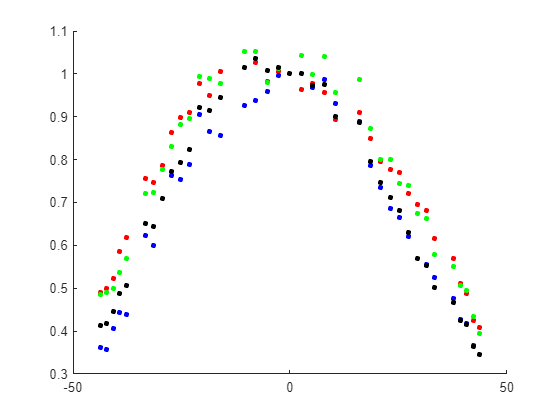


% hold on
% % scatter(theta, W_100_normaliseW_AS(:,[7, 4, 2, 9]),5,"cyan")
% hold off
% scatter(theta1, W_100_Further_normaliseW_AS(7,:), [], 'red')
% scatter(theta1, W_100_Further_normaliseW_AS(4,:), [], 'green')
% scatter(theta1, W_100_Further_normaliseW_AS(2,:), [], 'blue')

% VEML6040 Colour scatter
scatter(rad2deg(theta1), W_100_Further_normaliseW_VEML(1:4,:), 15, VEML_Colours, 'filled')

% hold on
% scatter(theta, W_100_normaliseW_VEML(:,1:4),5,"cyan")
% hold off
% scatter(theta1, W_100_Further_normaliseW_VEML(1,:), [], 'red')
% scatter(theta1, W_100_Further_normaliseW_VEML(2,:), [], 'green')
% scatter(theta1, W_100_Further_normaliseW_VEML(3,:), [], 'blue')

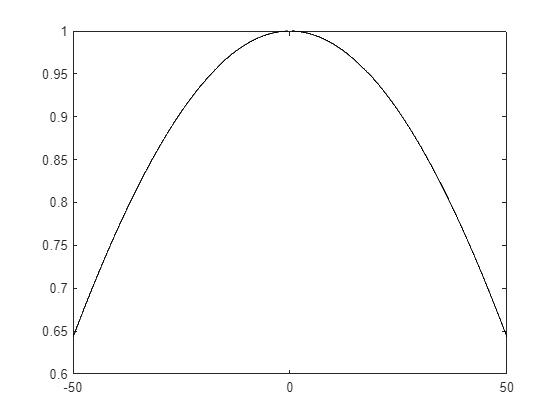

W_100_Further_normaliseW_AS([7, 4, 2, 9],:);

scaling_factor = cos(theta1');
AS = W_100_Further_normaliseW_AS([7, 4, 2, 9],:)./scaling_factor;

VEML = W_100_Further_normaliseW_VEML(1:4,:)./scaling_factor;

 t = -50:0.01:50;
 x = cos(deg2rad(t));
 plot(t,x,'k');

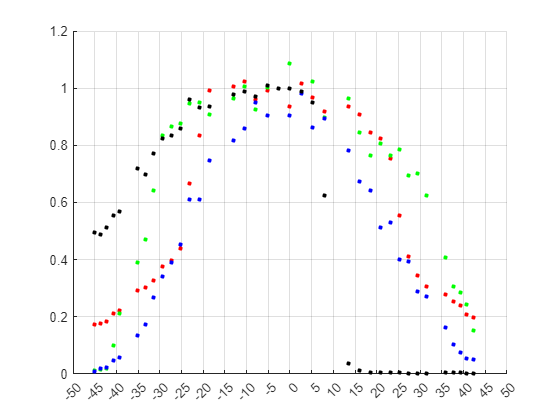


% scatter(rad2deg(theta1), AS, 10, VEML_Colours, 'filled')
% xticks(-50:5:50)
% grid on
scatter(rad2deg(thetaAS), AS, 10, VEML_Colours, 'filled')
xticks(-50:5:50)
grid on

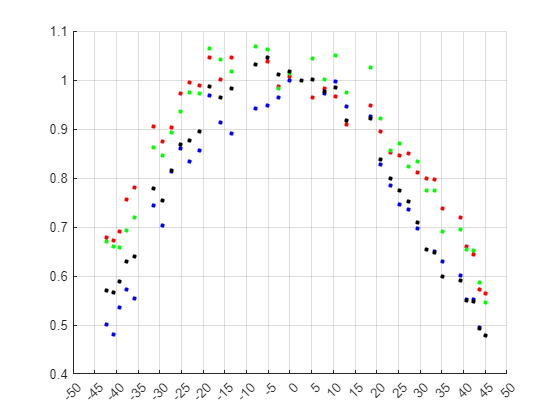


scatter(rad2deg(thetaVEML), VEML, 10, VEML_Colours, 'filled')
xticks(-50:5:50)
grid on



AS_R = AS(1,:);
AS_G = AS(2,:);
AS_B = AS(3,:);
AS_W = AS(4,:);

VEML_R = VEML(1,:);
VEML_G = VEML(2,:);
VEML_B = VEML(3,:);
VEML_W = VEML(4,:);

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(9,4);
    for j = 1:9
        for i = 1:4
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

function COLOUR_Scaled = scale2(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(14,4);
    for j = 1:14
        for i = 1:4
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

% function ANGLE_Scale